## 头模型投影数据仿真实验

### 1.1 利用Radon变换产生投影数据

clc;
close all;
I = phantom(1024);
theta = 0:179;
P = radon(I,theta);
figure;
imshow(I,[]);
figure;
imagesc(P),colormap('gray'),colorbar,title('180°平行束投影图像');
xlim([1 181])
ylim([1 1454])
legend('show')

### 1.2 利用推导的解析算法去计算投影数据

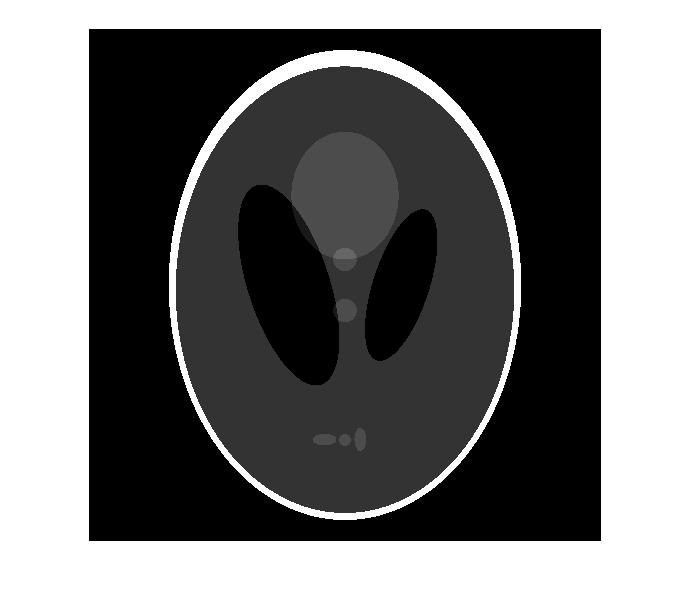

clc;
close all;
N = 512;
theta = 0:1:179;
I = phantom(N);
N_d = 2*ceil(norm(size(I)-floor((size(I)-1)/2)-1))+3;
E = importdata("Shepp-Logan.mat");
P = medfuncParallebeamForwardProjection(theta,N,N_d,E);
figure;
imshow(I,[]);

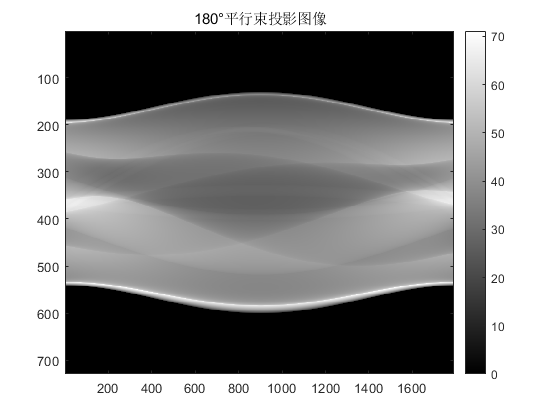

figure;
imagesc(P),colormap('gray'),colorbar,title('180°平行束投影图像');